clc
clear all
close all
rng(0)

# M3C Simulation

## Parameters

Simulation and control steps

Tf = 2;       % Total simulation time
Ts = 100e-6;    % Sampling time
Ns = Tf/Ts      % Number of sampling steps

Ns = 20000

Ti = 10e-6;	    % Integration step
Ni = Ts/Ti      % Number of integration steps between each ISR (Interrupt Service Routine)

Ni = 10

Tsim = linspace(0, Tf, Ni);

Ax0 = 7000;
Ay0 = 5000;
fx0 = 50;
fy0 = 50;
wx0 = 2*pi*fx0;
wy0 = 2*pi*fy0;

[ix_max, iy_max, is_max, vo_max, vB_max, VCdiff] = max_values(Ax0, Ay0)

ix_max = 200

iy_max = 280

is_max = 250

vo_max = 1000

vB_max = 12000

VCdiff = 0.0020

## External system (IOGrid)

Specifications

specsIOGrid = struct();

specsIOGrid.Ti = Ti;
specsIOGrid.Ax = Ax0;
specsIOGrid.fx = fx0;
specsIOGrid.Ay = Ay0;
specsIOGrid.fy = fy0;

Initial values

init_valsIOGrid = struct();

init_valsIOGrid.gx0 = 0;
init_valsIOGrid.gy0 = 0;

Create object

IOGrid = ClassIOGrid(specsIOGrid, init_valsIOGrid)

IOGrid =   ClassIOGrid with properties:

     Ti: 1.0000e-05
     Ax: 7000
     Ay: 5000
     fx: 50
     fy: 50
     wx: 314.1593
     wy: 314.1593
     gx: 0
     gy: 0
    vxy: [6×1 double]

## Modular Multilevel Matrix Converter (M3C)

Specifications

specsM3C = struct();

specsM3C.Ti  = Ti;       % Integration step
specsM3C.R   = 1e-3;     % Branch resistance
specsM3C.L   = 20e-3;    % Branch inductance
specsM3C.Csm = 20e-3;    % Submodule capacitance
specsM3C.Nsm = 4;        % Submodules per cluster
specsM3C.Rx  = 0.1e-3;   % Input filter resistance
specsM3C.Lx  = 1e-3;     % Input filter inductance
specsM3C.Ry  = 0.1e-3;   % Output filter resistance
specsM3C.Ly  = 1e-3;     % Output filter inductance

Initial values

init_valsM3C = struct();

init_valsM3C.is0 = zeros(9, 1);                     % Cluster current
init_valsM3C.vc0 = (vB_max + vo_max) * ones(9, 1);  % Cluster capacitor voltage

Create object

M3C = ClassM3C(specsM3C, init_valsM3C)

M3C =   ClassM3C with properties:

        A: [6×9 double]
    pinvA: [9×6 double]
        m: 9
        N: [9×4 double]
        n: 4
    pinvN: [4×9 double]
       Ti: 1.0000e-05
        R: 1.0000e-03
        L: 0.0200
      Csm: 0.0200
      Nsm: 4
        C: 0.0050
       Rx: 1.0000e-04
       Lx: 1.0000e-03
       Ry: 1.0000e-04
       Ly: 1.0000e-03
       As: [9×9 double]
       Bs: [9×9 double]
       Es: [9×9 double]
       Ad: [9×9 double]
       Bd: [9×9 double]
       Ed: [9×9 double]
      ixy: [6×1 double]
       is: [9×1 double]
      pis: [9×1 double]
       iB: [9×1 double]
       iz: [9×1 double]
       ie: [4×1 double]
       vc: [9×1 double]
       Ec: [9×1 double]

## Phase Locked Loops (PLL)

[ImperixPLL](https://imperix.com/doc/implementation/synchronous-reference-frame-pll)

Specifications

xi_pll = 1/sqrt(2);
wc_pll = 100*2*pi;

specsPLL = struct();

specsPLL.Ts = Ts;
specsPLL.kp = 2*xi_pll*wc_pll;
specsPLL.ki = wc_pll^2;
specsPLL.u_min = -Inf;
specsPLL.u_max = Inf;

Create objects

PLLx = ClassPLL(specsPLL)

PLLx =   ClassPLL with properties:

        g: 0
        w: 0
       Ts: 1.0000e-04
       kp: 888.5766
       ki: 3.9478e+05
    u_min: -Inf
    u_max: Inf
       b0: -868.8374
       b1: 908.3158
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

PLLy = ClassPLL(specsPLL)

PLLy =   ClassPLL with properties:

        g: 0
        w: 0
       Ts: 1.0000e-04
       kp: 888.5766
       ki: 3.9478e+05
    u_min: -Inf
    u_max: Inf
       b0: -868.8374
       b1: 908.3158
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

## TEB PI and Filter design

Plant model

% (Mean cluster capacitor voltage)/(Input current) transfer function
vc_mean_ref = vB_max + vo_max;
k_teb = Ax0/(6*vc_mean_ref) / M3C.C

k_teb = 17.9487

G_teb = k_teb*tf(1, [1, 0])


G_teb =
 
  17.95
  -----
    s
 
Continuous-time transfer function.


Closed loop poles assignment (one first and one second order poles)

% Second order pole
xi_acl = 1/sqrt(2);         % Damping factor
wn_acl = 2*pi*20;           % Natural frequency
% First order pole
alpha_acl = 2*pi*20;        % Natural frequency

% PI
kp_pi = wn_acl*(wn_acl+2*xi_acl*alpha_acl)/(k_teb*(2*wn_acl*xi_acl+alpha_acl))

kp_pi = 7.0013

ki_pi = wn_acl^2*alpha_acl/(k_teb*(2*wn_acl*xi_acl+alpha_acl))

ki_pi = 364.4271

% Filter
wn_filt = 2*wn_acl*xi_acl+alpha_acl

wn_filt = 303.3790

## Low Pass Filter for Mean Energy (LPF)

Specifications

specsLPF = struct();

specsLPF.Ts = Ts;
specsLPF.wn = wn_filt;

Initial values

init_valsLPF = struct();

init_valsLPF.y0 = mean(M3C.vc);

Create object

LPF = ClassLPF(specsLPF, init_valsLPF)

LPF =   ClassLPF with properties:

        Ts: 1.0000e-04
        wn: 303.3790
        b0: 0.0303
        b1: 0.0303
        a0: -1.9697
        a1: 2.0303
       y_t: 13000
     y_t_1: 13000
      yf_t: 13000
    yf_t_1: 13000

## Total Energy Balance Proportional Integral Controller (PI)

Specifications

specsPI = struct();

specsPI.Ts = Ts;
specsPI.kp = kp_pi;
specsPI.ki = ki_pi;
specsPI.u_min = -ix_max;
specsPI.u_max = ix_max;

Create object

PI = ClassPI(specsPI)

PI =   ClassPI with properties:

       Ts: 1.0000e-04
       kp: 7.0013
       ki: 364.4271
    u_min: -200
    u_max: 200
       b0: -6.9830
       b1: 7.0195
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

## Cluster Energy Model Predictive Controller (CEMPC)

Specifications

specsCEMPC = struct();

specsCEMPC.Ts = Ts;
specsCEMPC.m = M3C.m;
specsCEMPC.n = M3C.n;
specsCEMPC.N = M3C.N;
specsCEMPC.is_max = is_max;
specsCEMPC.vo_max = vo_max;
specsCEMPC.lambda_z = 2;
specsCEMPC.lambda_o = 0.1;
specsCEMPC.lmax = 10;
specsCEMPC.Np = 1;

Create object

CEMPC = ClassCEMPC(specsCEMPC)

CEMPC =   ClassCEMPC with properties:

            Ts: 1.0000e-04
             m: 9
             n: 4
             N: [9×4 double]
            NN: [9×4 double]
            Np: 1
        is_max: 250
        vo_max: 1000
      lambda_z: 2
      lambda_o: 0.1000
          lmax: 10
     options_i: [1×1 mpcActiveSetOptions]
     options_v: [1×1 mpcActiveSetOptions]
        ie_ref: [4×1 double]
        iz_ref: [9×1 double]
        vo_ref: 0
           iAi: [18×1 logical]
           iAv: [2×1 logical]
    exitflag_i: -3
    exitflag_v: -3
      exitflag: -3

Cluster energy and capacitor voltage references

vc_mean_ref = vB_max + vo_max;
Ec_mean_ref = M3C.C/2 * vc_mean_ref^2;

vc_ref = vc_mean_ref * ones(9, 1);
Ec_ref = Ec_mean_ref * ones(9, 1);

## Cluster Current Model Predictive Controller (CCMPC)

Specifications

% Model for control
specsM3C_CC = specsM3C;
specsM3C_CC.Ti = Ts;
M3C_CC = ClassM3C(specsM3C_CC, init_valsM3C);

specsCCMPC = struct();

specsCCMPC.Ts = Ts;
specsCCMPC.m = M3C.m;
specsCCMPC.Ad = M3C_CC.Ad;
specsCCMPC.Bd = M3C_CC.Bd;
specsCCMPC.lambda = 0.00005;

Create object

CCMPC = ClassCCMPC(specsCCMPC)

CCMPC =   ClassCCMPC with properties:

          Ts: []
           m: 9
          Ad: [9×9 double]
          Bd: [9×9 double]
      lambda: 5.0000e-05
     options: [1×1 mpcActiveSetOptions]
          iA: [18×1 logical]
          vs: [9×1 double]
    exitflag: -3

## Buffer

Specifications

specsBuffer = struct();

specsBuffer.Ts = Ts;
specsBuffer.Ns = Ns;
specsBuffer.m = M3C.m;
specsBuffer.n = M3C.n;
specsBuffer.A = M3C.A;

Create object

buffer = ClassBuffer(specsBuffer)

buffer =   ClassBuffer with properties:

                 Ts: 1.0000e-04
                 Ns: 20000
                  m: 9
                  n: 4
                  A: [6×9 double]
                 is: [9×20000 double]
                ixy: [6×20000 double]
                 iB: [9×20000 double]
                 iz: [9×20000 double]
                 ie: [4×20000 double]
                 vs: [9×20000 double]
                vxy: [6×20000 double]
                 vB: [9×20000 double]
                 vo: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ] (1×20000 double)
                 Ec: [9×20000 double]
                 vc: [9×20000 double]
            Ec_mean: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

## Neural Network

Emean = M3C.C/2 * vc_mean_ref^2 *1.1;            % Capacitor mean energy
E = Emean *((1+2*VCdiff)^2-1)   *ones(9, 1);     % Capacitor energy deviation
VX = Ax0                        *1.1*ones(3, 1); % Input voltage
VY = Ay0                        *1.1*ones(3, 1); % Output voltage
IX = ix_max                     *1.1*ones(3, 1); % Input current
IY = iy_max                     *1.1*ones(3, 1); % Output current

IE = is_max                     *2*ones(4, 1);   % L.I. circulating currents
VO = vo_max;                                     % Common mode voltage

Xmax = [Emean; E; VX; VY; IX; IY];
Ymax = [IE; VO];

net = load('ImitationLearning\ActualArchitecture\FFnet.mat', 'FFnet').FFnet

net =   dlnetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1
  View summary with summary.

% net = load('ImitationLearning\ArchitectureSearch\FFNN\Results\Architectures\A1L35N.mat', 'FFnet').FFnet

## Reference Frame Transform (RFT)

RFT = reference_frame_transforms();
RFT.abc2dq

ans = function_handle with value:
    @(g)(2/3)*[cos(g),cos(g-2*pi/3),cos(g+2*pi/3);-sin(g),-sin(g-2*pi/3),-sin(g+2*pi/3)]

RFT.abc2ab

ans =     0.6667   -0.3333   -0.3333
         0    0.5774   -0.5774


RFT.ab2abc

ans =     1.0000         0
   -0.5000    0.8660
   -0.5000   -0.8660


# Simulation

Reset

% vc0 = vc_mean_ref * ((2*rand(9, 1)-1) * 0.01 + 1);
% is0 = is_max * (2*rand(9, 1)-1);
% 
% init_valsM3C.is0 = is0;
% init_valsM3C.vc0 = vc0;

buffer = buffer.reset();
IOGrid = IOGrid.reset(init_valsIOGrid);
M3C = M3C.reset(init_valsM3C);
PLLx = PLLx.reset();
PLLy = PLLy.reset();
LPF = LPF.reset(init_valsLPF);
PI = PI.reset();
CEMPC = CEMPC.reset();
CCMPC = CCMPC.reset();

Run

% Initialize progress bar
h = waitbar(0, 'Simulating...');

for ts = 1:Ns

%% Measure external voltages
vxy = IOGrid.vxy;
vB = M3C.A' * vxy;

%% Input PLL
vxdq = RFT.abc2dq(PLLx.g) * vxy(1:3);
ixdq = RFT.abc2dq(PLLx.g) * M3C.ixy(1:3);
PLLx = PLLx.estimate(vxdq/norm(vxdq), wx0);

%% Output PLL
vydq = RFT.abc2dq(PLLy.g) * vxy(4:6);
iydq = RFT.abc2dq(PLLy.g) * M3C.ixy(4:6);
PLLy = PLLy.estimate(vydq/norm(vydq), wy0);

%% "Measure" converter cluster mean voltage
Ec = M3C.Ec;
vc = M3C.vc;

Ec_mean = mean(Ec);
vc_mean = mean(vc);

%% Low pass filter for mean cluster energy
LPF = LPF.filter(vc_mean);
vc_mean_filt = LPF.yf_t;
Ec_mean_filt = M3C.C / 2 * abs(vc_mean_filt)^2 * sign(vc_mean_filt);

%% Calculate input currents references (TEB PI)
% dq
PI = PI.control(vc_mean_ref, vc_mean_filt);
ixd_ref = PI.u_t;
ixq_ref = 0;
% abc
ixa_ref = ixd_ref * cos(PLLx.g)          - ixq_ref * sin(PLLx.g);
ixb_ref = ixd_ref * cos(PLLx.g - 2*pi/3) - ixq_ref * sin(PLLx.g - 2*pi/3);
ixc_ref = ixd_ref * cos(PLLx.g + 2*pi/3) - ixq_ref * sin(PLLx.g + 2*pi/3);

%% Calculate output currents references (Converter application)
% dq
iyd_ref = -100;
% if ts > Ns/2
%     iyd_ref = -200;
% end
iyq_ref = 0;
% abc
iyr_ref = iyd_ref * cos(PLLy.g)          - iyq_ref * sin(PLLy.g);
iys_ref = iyd_ref * cos(PLLy.g - 2*pi/3) - iyq_ref * sin(PLLy.g - 2*pi/3);
iyt_ref = iyd_ref * cos(PLLy.g + 2*pi/3) - iyq_ref * sin(PLLy.g + 2*pi/3);

%% Concatenate external currents references
ixy_ref = [ixa_ref; ixb_ref; ixc_ref; iyr_ref; iys_ref; iyt_ref];

%% Basic currents references
iB_ref = M3C.pinvA * ixy_ref;

%% Predict external voltages/currents
vB_pred = predict_basic_assuming_symmetrical(    vxy, CEMPC.Np, IOGrid, Ts, RFT, M3C.A);
iB_pred = predict_basic_assuming_symmetrical(M3C.ixy, CEMPC.Np, IOGrid, Ts, RFT, M3C.A);

%% Cluster energy MPC

% CEMPC = CEMPC.control(Ec, vB_pred, iB_pred);
% ie_ref = CEMPC.ie_ref;
% iz_ref = CEMPC.iz_ref;
% vo_ref = CEMPC.vo_ref;

X = [Ec_mean; Ec-Ec_mean; vxy; M3C.ixy];
x = dlarray(X ./ Xmax, 'CB');
y = double(extractdata(net.predict(x)));
Y = y .* Ymax;
ie_ref = Y(1:4);
iz_ref = M3C.N * ie_ref;
vo_ref = Y(5);

%% Cluster current MPC
is_ref = iz_ref + iB_ref;
CCMPC = CCMPC.control(is_ref, vc_mean_ref, M3C.is, vB, vo_ref);
vs = CCMPC.vs;

%% Store variables
buffer.is(:, ts)           = M3C.is;
buffer.ixy(:, ts)          = M3C.ixy;
buffer.iB(:, ts)           = M3C.iB;
buffer.iz(:, ts)           = M3C.iz;
buffer.ie(:, ts)           = M3C.ie;
buffer.vs(:, ts)           = vs;
buffer.vxy(:, ts)          = vxy;
buffer.vB(:, ts)           = vB;
buffer.vo(:, ts)           = vo_ref;
buffer.Ec(:, ts)           = Ec;
buffer.vc(:, ts)           = vc;
buffer.Ec_mean(ts)         = Ec_mean;
buffer.Ec_mean_filt(ts)    = Ec_mean_filt;
buffer.vc_mean(ts)         = vc_mean;
buffer.vc_mean_filt(ts)    = vc_mean_filt;

buffer.u_TEB(ts)           = PI.u_t;

buffer.gx(ts)              = IOGrid.gx;
buffer.wx(ts)              = IOGrid.wx;
buffer.gy(ts)              = IOGrid.gy;
buffer.wy(ts)              = IOGrid.wy;

buffer.gx_pll(ts)          = PLLx.g;
buffer.wx_pll(ts)          = PLLx.w;
buffer.gy_pll(ts)          = PLLy.g;
buffer.wy_pll(ts)          = PLLy.w;

buffer.ex_pll(ts)          = PLLx.e_t;
buffer.ux_pll(ts)          = PLLx.u_t;
buffer.ey_pll(ts)          = PLLy.e_t;
buffer.uy_pll(ts)          = PLLy.u_t;

buffer.is_ref(:, ts)       = is_ref;
buffer.ixy_ref(:, ts)      = ixy_ref;
buffer.iB_ref(:, ts)       = iB_ref;
buffer.iz_ref(:, ts)       = iz_ref;
buffer.ie_ref(:, ts)       = ie_ref;

buffer.exitflag_CEMPCi(ts) = CEMPC.exitflag_i;
buffer.exitflag_CEMPCv(ts) = CEMPC.exitflag_v;
buffer.exitflag_CCMPC(ts)  = CCMPC.exitflag;

buffer.iA_CEMPCi(ts)       = sum(CEMPC.iAi);
buffer.iA_CEMPCv(ts)       = sum(CEMPC.iAv);
buffer.iA_CCMPC(ts)        = sum(CCMPC.iA);

buffer.ixdq(:, ts)         = ixdq;
buffer.iydq(:, ts)         = iydq;
buffer.ixdq_ref(:, ts)     = [ixd_ref, ixd_ref];
buffer.iydq_ref(:, ts)     = [iyd_ref, iyd_ref];

buffer.vxdq(:, ts)         = vxdq;
buffer.vydq(:, ts)         = vydq;

%% Integrate external system and converter
for ti = 1:Ni
    % Update model
    M3C = M3C.step(CCMPC.vs, IOGrid.vxy, vo_ref);

    % Update external system
    IOGrid = IOGrid.step();
end

% Update progress bar
waitbar(ts/Ns, h, sprintf('Simulating: %d%%', round((ts/Ns)*100)));

end

% Close progress bar
close(h)

# Plot

buffer =   ClassBuffer with properties:

                 Ts: 1.0000e-04
                 Ns: 20000
                  m: 9
                  n: 4
                  A: [6×9 double]
                 is: [9×20000 double]
                ixy: [6×20000 double]
                 iB: [9×20000 double]
                 iz: [9×20000 double]
                 ie: [4×20000 double]
                 vs: [9×20000 double]
                vxy: [6×20000 double]
                 vB: [9×20000 double]
                 vo: [-9.8770 -5.2762 -2.7556 -3.3246 -6.4781 -5.7406 -4.5050 -3.2742 1.0481 7.2367 13.3295 18.3631 21.6010 23.6099 25.8076 26.5340 25.7049 27.2562 28.7490 30.0099 31.6789 33.1454 34.1518 31.7725 26.3234 24.5326 … ] (1×20000 double)
                 Ec: [9×20000 double]
                 vc: [9×20000 double]
            Ec_mean: [422500 4.2250e+05 4.2249e+05 4.2248e+05 4.2247e+05 4.2247e+05 4.2246e+05 4.2245e+05 4.2244e+05 4.2

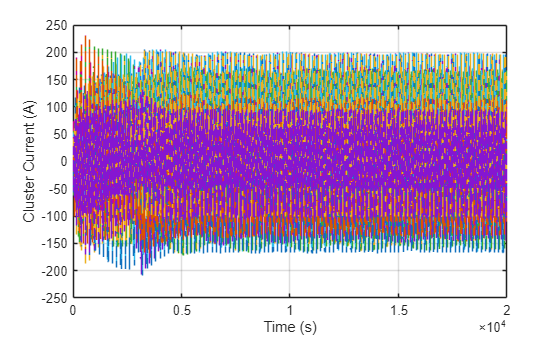

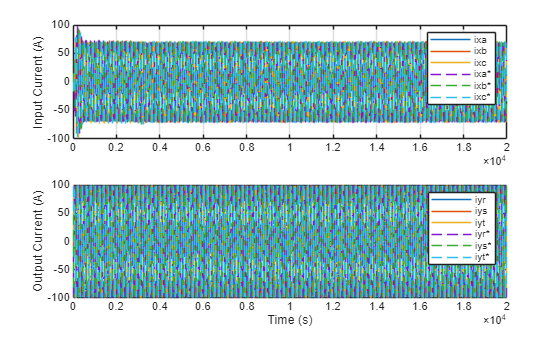

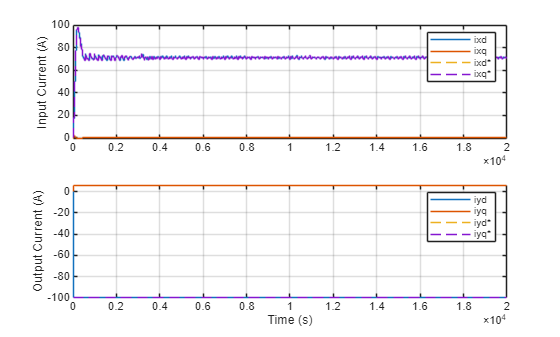

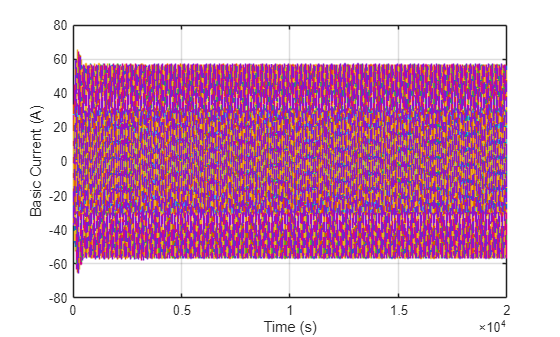

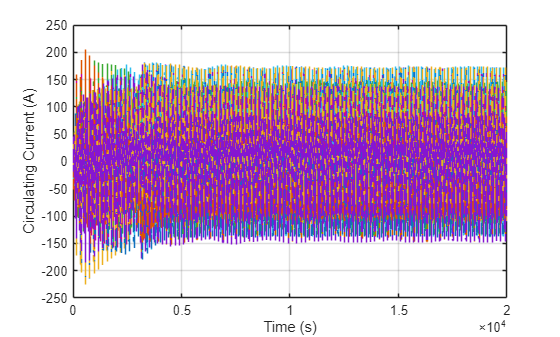

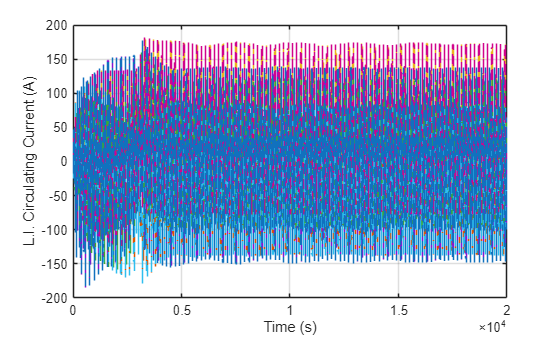

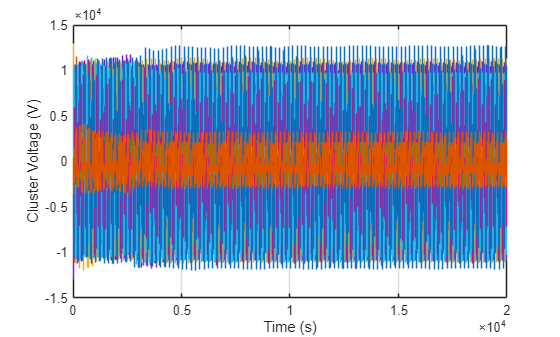

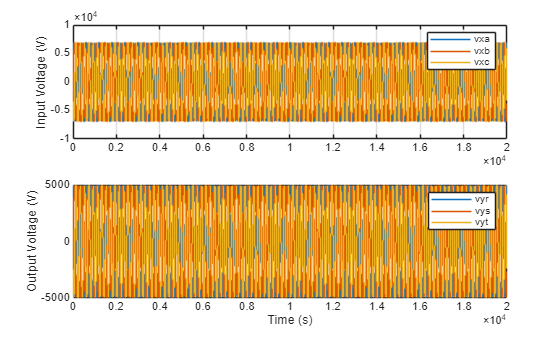

run("Plot.mlx")